# Magnetic Field of a Ring Filament

This script demonstrates magnetic field of ring shaped filament in vacuum.

#### Create Circle

radius = 10

radius = 10

center = [10 10 0]

center =     10    10     0


[Cx, Cy, Cz] = createParametricCircle(center, radius);

sample_count = 1000;
angles = linspace(0, 2*pi, sample_count);
x = Cx(angles);
y = Cy(angles);
z = Cz() * ones(1, sample_count);

figure;
plot3(x, y, z);
grid on
title('Generated Circle')
xlabel('x-axis')
ylabel('y-axis')

#### Pick an Observation Point

obs = [0 0 0]

obs =      0     0     0


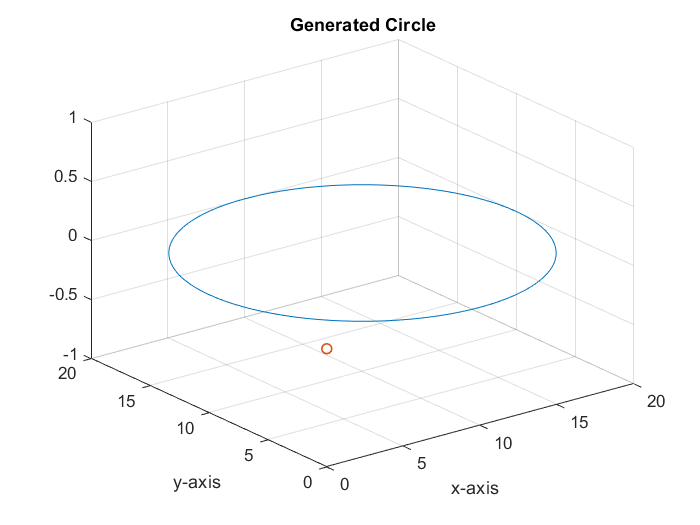


hold on;
scatter3(obs(1), obs(2), obs(3), 'LineWidth', 1);
hold off;

#### Calculate Magnetic Field Numerically

sample_count = 1000

sample_count = 1000

% Sample Circle
angles = linspace(0, 2*pi, sample_count);
x = Cx(angles);
y = Cy(angles);
z = Cz() * ones(1, sample_count);

% Calculate Magnetic Field from Sample Points
numeric = calculateMagneticField(x, y, z, obs);

#### Calculate Magnetic Field Theorically

a = radius;
rho = sqrt((obs(1)-center(1))^2+(obs(2)-center(2))^2);
z = abs(obs(3)-center(3));

theoretical = zeros(1,3);
if rho == 0
    if z == 0
        theoretical(3) = constants.mu_zero/2/a;
    else
        theoretical(3) = constants.mu_zero/2*a^2/sqrt((a^2+z^2)^3);
    end
else
    theoretical = ringB(a,rho,z);
end

#### Report Error and Configuration

fprintf("Created a circle with radius %0.2f centered at (%0.2f,%0.2f,%0.2f)", ...
    radius, center(1), center(2), center(3))

Created a circle with radius 10.00 centered at (10.00,10.00,0.00)

fprintf("Magnetic Field produced by the circle is calculated at (%0.2f,%0.2f,%0.2f):", ...
    obs(1), obs(2), obs(3));

Magnetic Field produced by the circle is calculated at (0.00,0.00,0.00):

fprintf(" -> Numerically: (%E,%E,%E) T", numeric(1), numeric(2), numeric(3));

 -> Numerically: (0.000000E+00,0.000000E+00,-2.396957E-08) T

fprintf(" -> Theoretically: (%E,%E,%E) T", ...
    theoretical(1), theoretical(2), theoretical(3));

 -> Theoretically: (0.000000E+00,0.000000E+00,-2.396973E-08) T

n = abs(numeric);
t = abs(theoretical);
error = abs(numeric - theoretical) / theoretical * 100;
fprintf("Percentage error is %0.2f.", error);

Percentage error is -0.00.